# Matrix Completion of Union-of-subspaces data (dims=15x500)

Demonstrates usage of vmc.m in small-scale setting

## Generate random UoS data

n = 15;     %ambient dim
r = 3;      %subspace dim
k = 5;      %number of subspaces
p = 100;    %points per subspace
m = 12;     %samples per column
sig = 0;%0.03;  %noise level

Xtrue = [];
for i=1:k
    U = orth(randn(n,r));
    Xtrue = [Xtrue, U*randn(r,p)];
end
s = size(Xtrue,2);

disp('job done')

job done


## Subsample data uniformly at random over each column

sampmask = false(n,s);
for j = 1:s
    rind = randperm(n);
    sampmask(rind(1:m),j) = true;
end
samples0 = Xtrue(sampmask);
samples = samples0 + sig*randn(size(samples0));
Xinit = zeros(n,s);
Xinit(sampmask) = samples;
epsilon = norm(samples0-samples); %find noise level
disp('job done')

job done


## Verify data is high-rank

r = rank(Xtrue,1e-6); %rank in original domain
R = rank((Xtrue'*Xtrue).^2,1e-6); %rank in lifted domain
N = nchoosek(n+1,2);
fprintf('original matrix: dim = %d-by-%d,\t rank=%d\n',n,s,r);

original matrix: dim = 15-by-500,	 rank=15


fprintf('lifted matrix:   dim = %d-by-%d,\t rank=%d\n',N,s,R);

lifted matrix:   dim = 120-by-500,	 rank=30


disp('job done')

job done


## Run low-rank matrix completion (LRMC) for comparison

options_nn.lambda = 1e5;
options_nn.mu = 10;
options_nn.niter = 1000;
Xlrmc = lrmc_admm(Xinit,sampmask,samples,options_nn);
%Xlrmc = lrmc_cvx(sampmask,samples); % CVX version
fprintf('LRMC NRMSE = %1.2e\n',norm(Xlrmc-Xtrue,'fro')/norm(Xtrue,'fro'));

LRMC NRMSE = 3.10e-01


disp('job done')

job done


## Run variety-based matrix completion (VMC)

options = [];
options.d = 2; %kernel degree
options.epsilon = epsilon; %estimated noise level
% see inside vmc.m for other options
[Xvmc,cost,update,error] = vmc(Xinit,sampmask,samples,options,Xtrue);

VMC set options.eigcomp='lift-svd' based on problem size
VMC reached exit tolerance at iter 2520


fprintf('VMC NRMSE = %1.2e\n',norm(Xvmc-Xtrue,'fro')/norm(Xtrue,'fro'));

VMC NRMSE = 1.86e-05


disp('job done')

job done


## Display columnwise errors

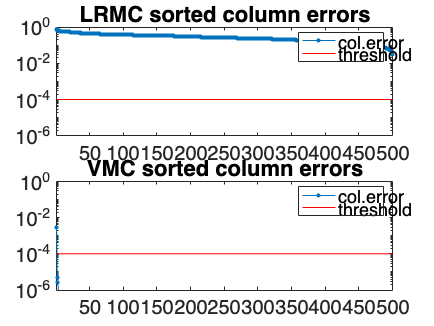

sampmaskc = ~sampmask; %unsampled locations
colerr_vmc = zeros(1,s);
colerr_lrmc = zeros(1,s);
for j = 1:s
    colerr_vmc(j) = norm(Xvmc(:,j)-Xtrue(:,j))/norm(Xtrue(:,j));
    colerr_lrmc(j) = norm(Xlrmc(:,j)-Xtrue(:,j))/norm(Xtrue(:,j));
end
[colerr_vmc,idx] = sort(colerr_vmc,'descend');
[colerr_lrmc,idx] = sort(colerr_lrmc,'descend');
errthresh = 1e-4;

figure(1);
subplot(2,1,1);
semilogy(colerr_lrmc,'.-'); title('LRMC sorted column errors');
hold on
line([0 s],[errthresh errthresh],'Color','red');
hold off
axis([1 s 1e-6 1]);
legend('col.error','threshold');
subplot(2,1,2);
semilogy(colerr_vmc,'.-'); title('VMC sorted column errors');
hold on
line([0 s],[errthresh errthresh],'Color','red');
hold off
legend('col.error','threshold');
axis([1 s 1e-6 1]);

fprintf('LRMC recovered %2.1f%% columns (%d of %d) with err < %1.1e\n',(nnz(colerr_lrmc < errthresh)/s)*100,nnz(colerr_lrmc < errthresh),s,errthresh);

LRMC recovered 0.0% columns (0 of 500) with err < 1.0e-04


fprintf('VMC recovered %2.1f%% columns (%d of %d) with err < %1.1e\n',(nnz(colerr_vmc < errthresh)/s)*100,nnz(colerr_vmc < errthresh),s,errthresh);

VMC recovered 99.8% columns (499 of 500) with err < 1.0e-04


disp('job done')

job done
